load('webcamsSceneReconstruction.mat');

% 导入图片
I1 = imread('sceneReconstructionLeft.jpg');
I2 = imread('sceneReconstructionRight.jpg');

% rectify：将两个相机的原图像投影到一个新的、共同的平面上
[J1, J2] = rectifyStereoImages(I1,I2,stereoParams);

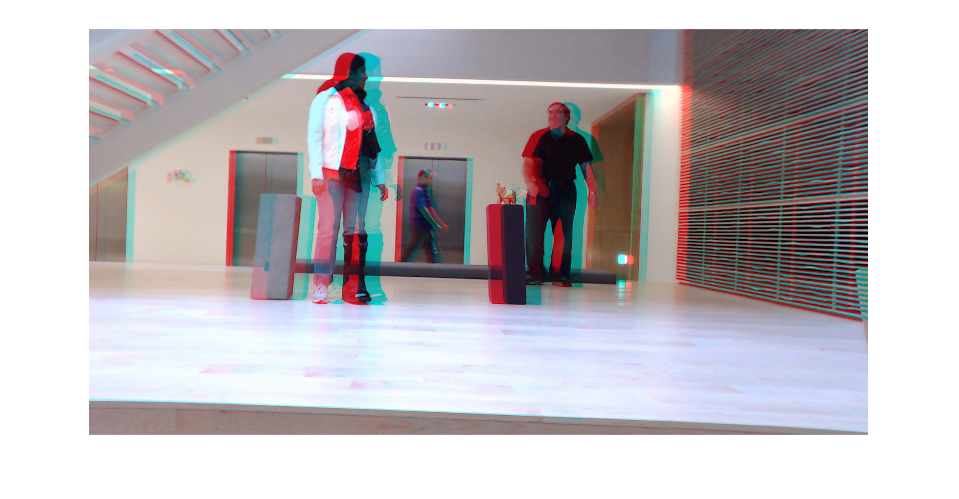

figure 
imshow(cat(3,J1(:,:,1),J2(:,:,2:3)),'InitialMagnification',50);

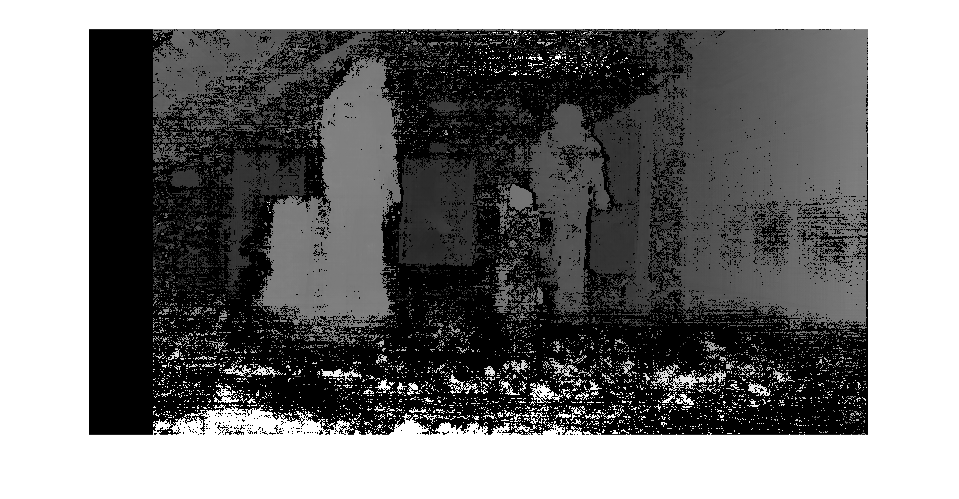

% disparity：能够反映物体的距离远近
disparityMap = disparitySGM(rgb2gray(J1),rgb2gray(J2));
figure 
imshow(disparityMap,[0,64],'InitialMagnification',50);

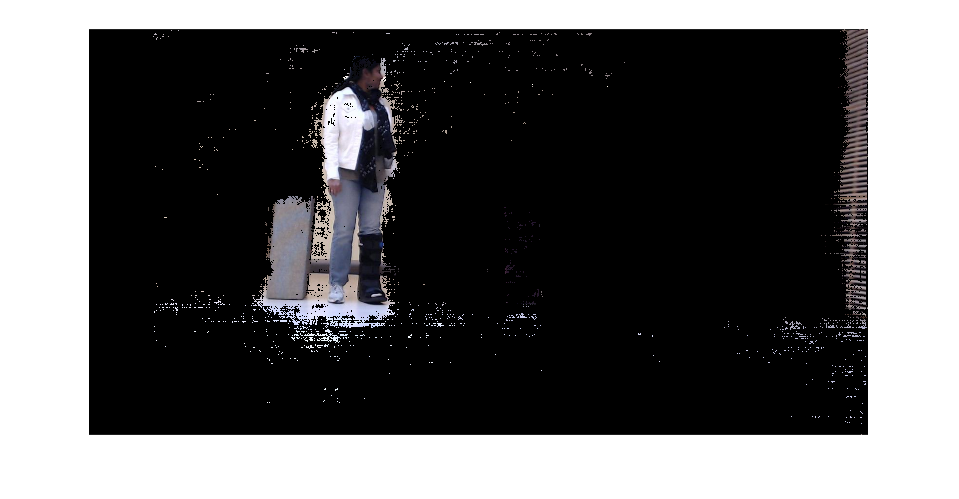

% reconstruct
xyzPoints = reconstructScene(disparityMap,stereoParams);
% 输出距离相机 3.2-3.7 米的图像
Z = xyzPoints(:,:,3);
mask = repmat(Z > 3200 & Z < 3700,[1,1,3]);
J1(~mask) = 0;
imshow(J1,'InitialMagnification',50);